# Practical Coding and Math: HW 5, Statistics

Hannah Quick

24-September 2024

## Load the data

Download monthly sea level data from Charleston, SC using this PSMSL dataset. You can download it directly or copy and paste it into a .txt file. 	

1. Read in the sea level data, creating separate vectors for the date (first column) and the sea level (second column).

% Read in data
data = readtable("charleston.csv");

% Separate vectors
year = data.year

year = 1.0e+03 *

    1.9218
    1.9219
    1.9220
    1.9220
    1.9221
    1.9222
    1.9223
    1.9224
    1.9225
    1.9225


sea_lvl = data.sea_level

sea_lvl =         7033
        6939
        6893
        6768
        6853
        6838
        6832
        6914
        6893
        6838


## Histograms

Plot the histograms of sea level data for these time periods on top of each other: 1923-1942, 2003-2022

% First, index the data to time slices
period = [1923, 1942];
time_index_23_42 = year>=period(1) & year<=period(2);
time_slice_23_42 = year(time_index_23_42);
sea_slice_23_42 = sea_lvl(time_index_23_42);

period = [2003, 2022];
time_index_03_02 = year>=period(1) & year<=period(2);
time_slice_2003_2022 = year(time_index_03_02);
sea_slice_2003_2022 = sea_lvl(time_index_03_02);


% Now, make the histograms
data = sea_slice_23_42;
data_mean = mean(data)

data_mean = 6.8870e+03

data_median = prctile(data,50) %second input is percentile (median is 50th)

data_median = 6.8795e+03


data_lin = linspace(min(data),max(data),100);
data_gauss = (1/(sqrt(2*pi)))*exp(-0.5*((data_lin-mean(data))/std(data)).^2);

figure;
histogram(data,'Normalization','probability');hold on
plot(data_median.*ones(1,5),linspace(0,0.3,5),'b-','linewidth',4);
plot(data_mean.*ones(1,5),linspace(0,0.3,5),'r--','linewidth',4);
plot(data_lin,data_gauss./2,'k-','linewidth',2)

% Calculations for 2003-2022
data = sea_slice_2003_2022;
data_mean = mean(data)

data_mean = 7.1784e+03

data_median = prctile(data,50) %second input is percentile (median is 50th)

data_median = 7.1795e+03

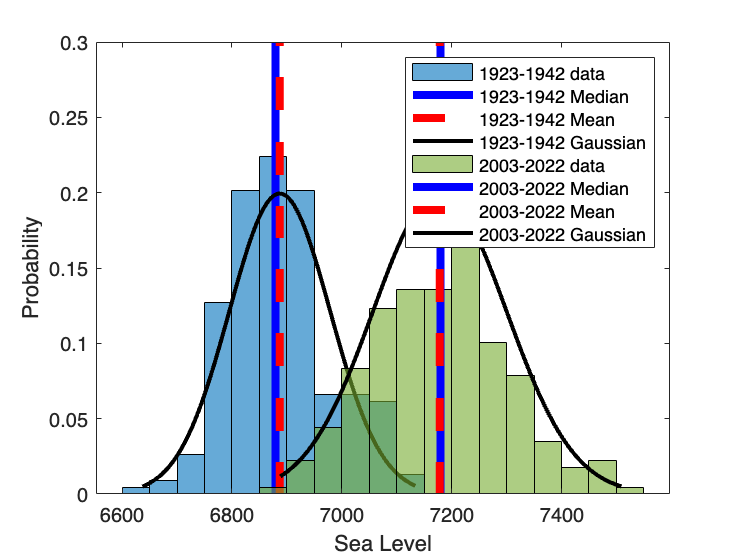


data_lin = linspace(min(data),max(data),100);
data_gauss = (1/(sqrt(2*pi)))*exp(-0.5*((data_lin-mean(data))/std(data)).^2);

histogram(data,'Normalization','probability');
plot(data_median.*ones(1,5),linspace(0,0.3,5),'b-','linewidth',4);
plot(data_mean.*ones(1,5),linspace(0,0.3,5),'r--','linewidth',4);
plot(data_lin,data_gauss./2,'k-','linewidth',2)

%% For all data
% data = sea_lvl;
% data_mean = mean(data)
% data_median = prctile(data,50) %second input is percentile (median is 50th)
% 
% data_lin = linspace(min(data),max(data),100);
% data_gauss = (1/(sqrt(2*pi)))*exp(-0.5*((data_lin-mean(data))/std(data)).^2);
% 
% histogram(data,'Normalization','probability');
% plot(data_median.*ones(1,5),linspace(0,0.3,5),'b-','linewidth',4);
% plot(data_mean.*ones(1,5),linspace(0,0.3,5),'r--','linewidth',4);
% plot(data_lin,data_gauss./2,'k-','linewidth',2)


ylabel("Probability")
xlabel("Sea Level")
legend("1923-1942 data", "1923-1942 Median", "1923-1942 Mean", "1923-1942 Gaussian", ...
    "2003-2022 data", "2003-2022 Median", "2003-2022 Mean", "2003-2022 Gaussian")
hold off

## May Means

Calculate mean May sea level for each of these two periods

% First, find data points that correspond to May. 

% There's probably a much more efficient way to do this. 

day_decimal = year-floor(year) % extract just the decimal element of the decimal year

day_decimal =     0.7917
    0.8750
    0.9583
    0.0417
    0.1250
    0.2083
    0.2917
    0.3750
    0.4583
    0.5417


May_index = zeros(length(year), 1) % initialize variable to store logical array

May_index =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for i=1:length(year)
if ~isinteger(floor(year(i))/4)
May_index(i) =  day_decimal(i)>=121/365 && day_decimal(i)<=151/365;
% For a non-leap year, May 1 is the 121st day of the year and May 31 is the 151st day of the year. 
elseif isinteger(floor(year)/4)
May_index(i) =    day_decimal(i)>=122/366 && day_decimal(i)<=152/366;
% For a leap year, May 1 is the 122nd day of the year and May 31 is the 152st day of the year. 

end     
end
May_index = logical(May_index);

% Next, find data points that are both in May and in date range
May_23_43 = sea_lvl(time_index_23_42 & May_index);
May_03_22 = sea_lvl(time_index_03_02 & May_index);

% take the means
mean_old_May = mean(May_23_43)

mean_old_May = 6.8822e+03

mean_recent_May = mean(May_03_22)

mean_recent_May = 7.1672e+03

all_May_mean = mean(sea_lvl(May_index))

all_May_mean = 7.0436e+03

## T-values, Null Hypothesis

Calculate t-values for each of these time periods.

Evaluate whether we can reject the null hypothesis at a 95% confidence level that the mean May sea level from each of these periods is the same as the long-term mean of May sea level (and if so, at what level) 

*Science question*: Is the mean May sea level from each of these periods the same as the long-term mean of May sea level?

*Statistical question*: Can we reject the null hypothesis at a 95% confidence level that the mean from these periods was within the distribution of the historical average for long-term May sea level?

% 2003-2022
data_subset = May_03_22;
data_all = sea_lvl(May_index);
confidence = 0.95; % 95 percent confidence interval

nyr = length(data_subset);
a = 1-confidence;
df = nyr-1;
%For one tail, tcrit = tinv(1-a,df)  

tcrit = tinv(1-a/2,df); %(for two tail)

%tval = (mean(aug_recent) - augtemp_mean)/(std(aug_recent)/sqrt(nyr-1))
tval = (mean(data_subset) - mean(data_all))/(std(data_subset)/sqrt(nyr-1));
test = tval>tcrit

test = logical
   1


p_recent=1-cdf('t',tval,nyr-1)

p_recent = 4.7527e-08

Because tval>tcrit, then we can reject the null hypothesis at the chosen confidence level.

Based on the p-value, there is a high chance that the mean of the distribution has changed.

% 1923-1942
data_subset = May_23_43;
data_all = sea_lvl(May_index);
confidence = 0.95; % 95 percent confidence interval

nyr = length(data_subset);
a = 1-confidence;
df = nyr-1;
%For one tail, tcrit = tinv(1-a,df)  

tcrit = tinv(1-a/2,df) %(for two tail)

tcrit = 2.1009


%tval = (mean(aug_recent) - augtemp_mean)/(std(aug_recent)/sqrt(nyr-1))
tval = (mean(data_subset) - mean(data_all))/(std(data_subset)/sqrt(nyr-1))

tval = -11.5216

test2 = abs(tval)>abs(tcrit)

test2 = logical
   1



p_old=1-cdf('t',abs(tval),nyr-1)

p_old = 4.8438e-10

The absolute magnitude of the t-value is greater than the magnitude of t-critical, so we can reject the null hypothesis at the chosen confidence level. The negative t value indicates that the mean sea level was less in the period from 1923-1942 than during the overall period for which data are available. 